依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Final PCA

[~,FinalPcaScore]=TransferLearning.UnifiedPcaModel(Paradigm="光声");

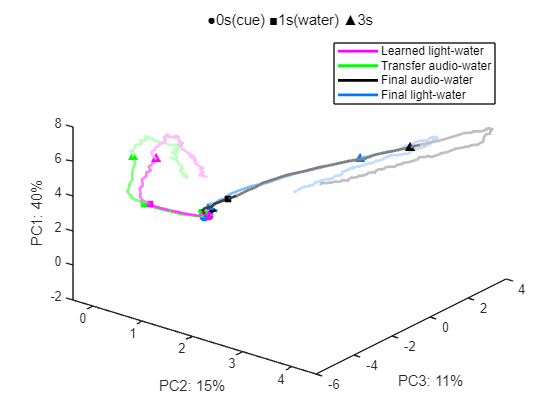

PCs=[2,3,1];
PcaScore=permute(FinalPcaScore.Score{PCs,:,["Learned","Transfer_hit","Final","Final_origin"]},[3,1,2]);
LinesPC=table;
LinesPC.Points=PcaScore;
LinesPC.Color=GlobalOptimization.ColorAllocate(4,[1,1,1;1,1,1]);
Markers=table;
Markers.Index=[24;32;48];
Markers.Shape=('os^')';
figure;
Lines=UniExp.SegmentFadePlot(LinesPC,Markers,PatchArguments={'LineWidth',2});
UniExp.PcAxLabels(table(PCs',FinalPcaScore.Explained(PCs),'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]));
legend(Lines,["Learned light-water","Transfer audio-water","Final audio-water","Final light-water"],Location='northeast');
title('●0s(cue) ■1s(water) ▲3s');
Explained=FinalPcaScore.Explained(PCs);
view(90*Explained(2)/(Explained(1)+Explained(2)),90*(1-Explained(3)/sum(Explained)));
%3D无法生成矢量图，只能点阵
print(TransferLearning.ProjectPath('FinalMOpPca.png'),'-dpng','-r200');